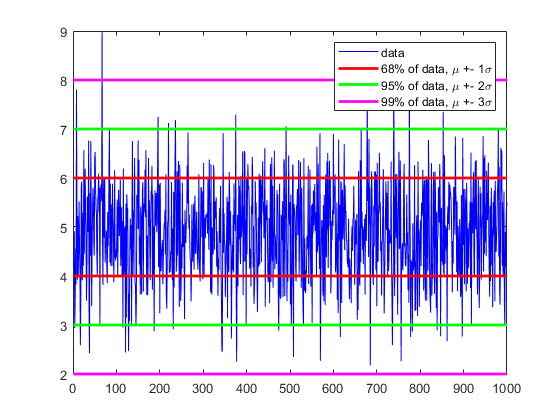

clear variables; close all; clc;

% generate gaussian data
mu = 5;
sigma = 1;
number_of_data = 1000;
% rng('default');
data = mu + sigma.*randn(number_of_data, 1);

% plot data
plot(data,'b')
hold on;
line([1 number_of_data],[mu+sigma mu+sigma],'Color','red','LineWidth',2);
line([1 number_of_data],[mu+2*sigma mu+2*sigma],'Color','green','LineWidth',2);
line([1 number_of_data],[mu+3*sigma mu+3*sigma],'Color','m','LineWidth',2);
line([1 number_of_data],[mu-sigma mu-sigma],'Color','red','LineWidth',2);
line([1 number_of_data],[mu-2*sigma mu-2*sigma],'Color','green','LineWidth',2);
line([1 number_of_data],[mu-3*sigma mu-3*sigma],'Color','m','LineWidth',2);
legend('data','68% of data, \mu +- 1\sigma','95% of data, \mu +- 2\sigma','99% of data, \mu +- 3\sigma')

mean(data)

ans = 4.8925

std(data)

ans = 0.9886

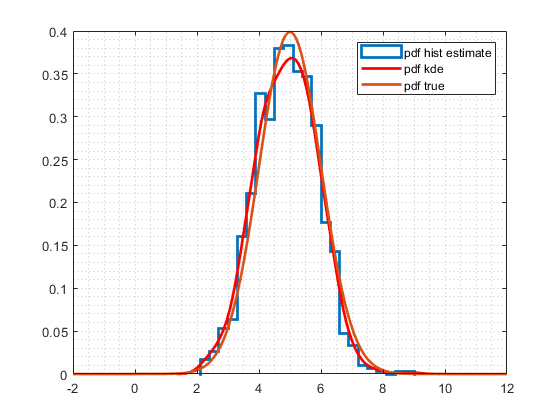

% histogram
figure
histogram(data,'Normalization','pdf','DisplayStyle','stairs','LineWidth',2)
hold on; grid minor;

% kernel density estimation
[f,xi] = ksdensity(data);
plot(xi,f,'r','LineWidth',2)

% true probability density function
xstart = mu-7;
xend = mu+7;
xlim([xstart xend])
dx = 1e-4;
x = xstart:dx:xend;
pdf = normpdf(x,mu,sigma);
plot(x,pdf,'LineWidth',2)
legend('pdf hist estimate','pdf kde','pdf true')

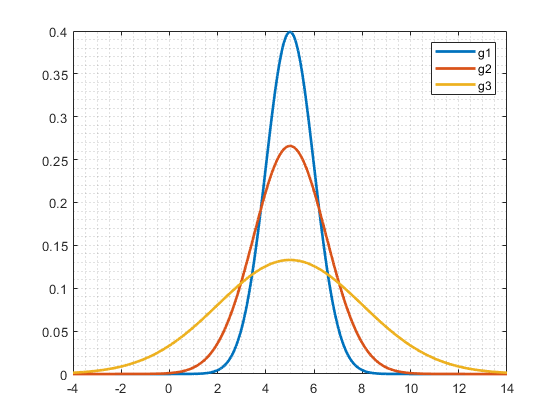

% compare gaussian distributions
xstart = mu-9*sigma;
xend = mu+9*sigma;
x = xstart:dx:xend;
g11 = normpdf(x,mu,sigma);
g12 = normpdf(x,mu,sigma*1.5);
g13 = normpdf(x,mu,sigma*3);
figure
plot(x,g11,'LineWidth',2)
hold on; grid minor;
plot(x,g12,'LineWidth',2)
plot(x,g13,'LineWidth',2)
legend('g1','g2','g3')
xlim([xstart xend])